task = 'contrLocalBadpt';
folder = '/Volumes/CONSENPHAS-Q5078';
% folder = 'Z:/';
folder = '/Users/henry/Documents/local-data';

% load behavioural data table
file = fullfile(folder,task,'derivatives','eeg','ic','compiled-data-struct.mat');
load(file, 'df')
df = struct2table(df);

pids = unique(df.pid); 
for n = 1:numel(pids)
    ix = df.pid == pids(n); 
    contr = df.contrast(ix); 
    contr = contr(contr > 0 & contr < 1);
    thr = 10.^mean(log10(contr));
    df.ratio_contr(ix) = df.contrast(ix) ./ thr;
end

df.y = df.accuracy;
df.phi = -abs(circ_dist(df.phi_echt, df.phase_offset));

df.x = df.ratio_contr; 
df.x1 = df.ratio_contr.^2;
df.x2 = df.ratio_contr.^.5;

m0 = fitglme(df, 'y~(x+x1+x2) + (1|pid)','distribution','binomial','fitmethod','laplace')

m0 = Generalized linear mixed-effects model fit by ML

Model information:
    Number of observations           22020
    Fixed effects coefficients           4
    Random effects coefficients         32
    Covariance parameters                1
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       Laplace

Formula:
    y ~ 1 + x + x1 + x2 + (1 | pid)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    22727    22767    -11358           22717   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF       pValue        Lower       Upper   
    {'(Intercept)'}         0.59977    0.11539     5.1978    22016    2.0343e-07      0.3736     0.82593
    {'x'          }          5.7178    0.28922      19.77    22016    3.0302e-86      5.1509      6.2847
    {'x1'         

anova(m0)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue    
    {'(Intercept)'}        27.017    1      22016    2.0343e-07
    {'x'          }        390.85    1      22016    3.0302e-86
    {'x1'         }        128.72    1      22016    9.4646e-30
    {'x2'         }        334.11    1      22016    4.3337e-74


m1 = fitglme(df, 'y~(x+x1+x2)*amp_echt + (1|pid)','distribution','binomial','fitmethod','laplace')

m1 = Generalized linear mixed-effects model fit by ML

Model information:
    Number of observations           19347
    Fixed effects coefficients           8
    Random effects coefficients         32
    Covariance parameters                1
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       Laplace

Formula:
    y ~ 1 + amp_echt*x + amp_echt*x1 + amp_echt*x2 + (1 | pid)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    20081    20151    -10031           20063   

Fixed effects coefficients (95% CIs):
    Name                   Estimate      SE           tStat        DF       pValue        Lower         Upper    
    {'(Intercept)'}           0.51375      0.13983       3.6741    19339     0.0002393       0.23967      0.78782
    {'amp_echt'   }         0.0050779     0.004935        1.029    19339      

anova(m1)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat        DF1    DF2      pValue    
    {'(Intercept)'}           13.499    1      19339     0.0002393
    {'amp_echt'   }           1.0587    1      19339       0.30351
    {'x'          }           160.51    1      19339    1.2246e-36
    {'x1'         }           56.716    1      19339    5.2574e-14
    {'x2'         }           132.35    1      19339    1.5781e-30
    {'amp_echt:x' }        0.0033902    1      19339       0.95357
    {'amp_echt:x1'}           0.3624    1      19339       0.54719
    {'amp_echt:x2'}          0.18329    1      19339       0.66857


compare(m0,m1)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    m0       5     22727    22767    -11358                               
    m1       9     20081    20151    -10031    2654.1    4          0     


m2 = fitglme(df, 'y~(x+x1+x2)*phi + (1|pid)','distribution','binomial','fitmethod','laplace')

m2 = Generalized linear mixed-effects model fit by ML

Model information:
    Number of observations           19347
    Fixed effects coefficients           8
    Random effects coefficients         32
    Covariance parameters                1
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       Laplace

Formula:
    y ~ 1 + phi*x + phi*x1 + phi*x2 + (1 | pid)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    20082    20153    -10032           20064   

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat       DF       pValue        Lower       Upper   
    {'(Intercept)'}           0.5862     0.16469      3.5595    19339     0.0003724     0.26341       0.909
    {'phi'        }        0.0030558    0.074525    0.041003    19339       0.96729    -0.14302     0.149

anova(m2)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat        DF1    DF2      pValue    
    {'(Intercept)'}            12.67    1      19339     0.0003724
    {'phi'        }        0.0016813    1      19339       0.96729
    {'x'          }           127.01    1      19339    2.2822e-29
    {'x1'         }           57.196    1      19339    4.1205e-14
    {'x2'         }           99.852    1      19339    1.8717e-23
    {'phi:x'      }          0.27737    1      19339       0.59844
    {'phi:x1'     }           1.6473    1      19339       0.19935
    {'phi:x2'     }         0.065408    1      19339       0.79815


compare(m0,m2)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    m0       5     22727    22767    -11358                               
    m2       9     20082    20153    -10032    2652.5    4          0     


m3 = fitglme(df, 'y~(x+x1+x2)*phi*amp_echt + (1|pid)','distribution','binomial','fitmethod','laplace')

m3 = Generalized linear mixed-effects model fit by ML

Model information:
    Number of observations           19347
    Fixed effects coefficients          16
    Random effects coefficients         32
    Covariance parameters                1
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       Laplace

Formula:
    y ~ 1 + amp_echt*phi + amp_echt*x + phi*x + amp_echt*x1 + phi*x1 + amp_echt*x2 + phi*x2 + amp_echt:phi:x + amp_echt:phi:x1 + amp_echt:phi:x2 + (1 | pid)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    20084    20218    -10025           20050   

Fixed effects coefficients (95% CIs):
    Name                       Estimate      SE           tStat       DF       pValue        Lower         Upper    
    {'(Intercept)'    }           0.26216      0.21952      1.1942    19331        0.2324      

anova(m3)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                       FStat       DF1    DF2      pValue    
    {'(Intercept)'    }          1.4262    1      19331        0.2324
    {'amp_echt'       }          4.8842    1      19331      0.027115
    {'phi'            }          2.0717    1      19331       0.15007
    {'x'              }          50.465    1      19331    1.2553e-12
    {'x1'             }          26.615    1      19331    2.5075e-07
    {'x2'             }          33.485    1      19331    7.2943e-09
    {'amp_echt:phi'   }          3.8748    1      19331       0.04903
    {'amp_echt:x'     }         0.84381    1      19331       0.35832
    {'phi:x'          }          0.1123    1      19331       0.73754
    {'amp_echt:x1'    }        0.014312    1      19331       0.90478
    {'phi:x1'         }         0.25764    1      19331       0.61175
    {'amp_echt:x2'    }          2.3759    1      19331       0.12324
    {'phi:x2'     

compare(m2,m3)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue  
    m2        9    20082    20153    -10032                                 
    m3       17    20084    20218    -10025    14.272    8          0.074955


## compute AIC weights

Ms = {m0, m1, m2, m3}; 

aics = nan(1,  numel(Ms)); 
bics = aics;
liks = aics;
for n = 1:numel(aics)
    aics(n) = Ms{n}.ModelCriterion.AIC;
    bics(n) = Ms{n}.ModelCriterion.BIC;
    liks(n) = Ms{n}.LogLikelihood;
end
aic_change = aics - min(aics);
bic_change = bics - min(bics);

aicw = exp(-.5*aic_change); 
aicw = aicw ./ sum(aicw);

bicw = exp(-.5*bic_change);
bicw = bicw ./ sum(bicw);

bw = .3; 
jit = .15; 
clf
nexttile
hold on 
bar((1:numel(Ms))-jit, aicw, bw, 'edgecolor','none')
bar((1:numel(Ms))+jit, bicw, bw, 'edgecolor','none')
xticks(1:numel(Ms))
xticklabels({'null (behaviour)','power','phase','power*phase'})
ylabel('model weight')
legend({'AIC','BIC'})
title('Model comparison')

save(fullfile(folder,task,'plot-data','log-reg-IC.mat'), 'aics','bics','aicw','bicw','liks')

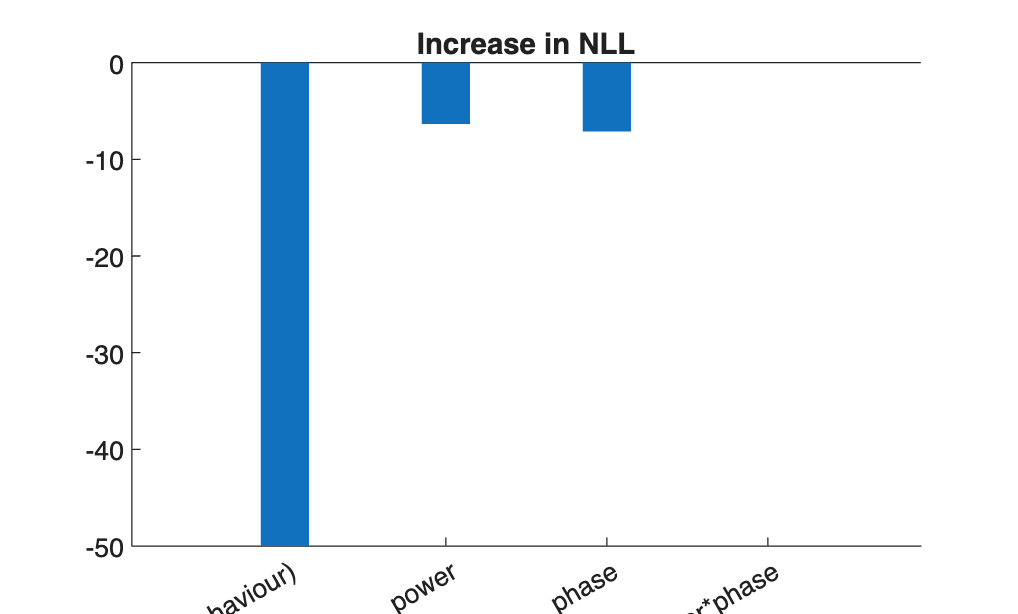

bf10s =    Inf   Inf   Inf


clf
nexttile
hold on 
bar((1:numel(Ms)), (liks-max(liks)), bw, 'edgecolor','none')
% bar((1:numel(Ms))+jit, bics-bics(1), bw, 'edgecolor','none')
xticks(1:numel(Ms))
xticklabels({'null (behaviour)','power','phase','power*phase'})

ylim([-50,0])
% ylabel('model weight')
% legend({'LogLik'})
title('Increase in NLL')